root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data";
testdate = "26_04_22";

file_num = 2;
path = root_dir + "/" + testdate + "/catapult_data/*.csv";
file_names = dir(path)

file_names = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


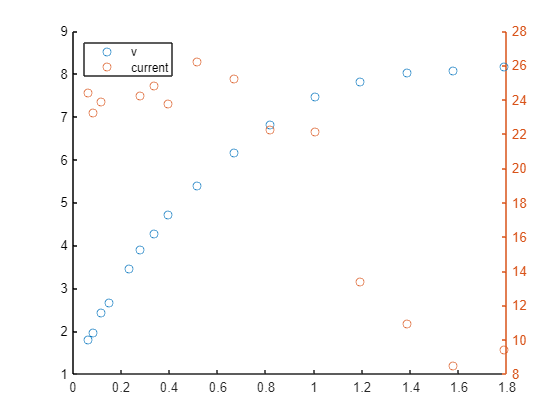

current_file = file_names(file_num);

file = importdata(strcat(current_file.folder, '\', current_file.name), ",");
catapult_data = file.data(file.data(:,1) < 2000000, :);
clf
hold on
scatter(catapult_data(:,1), catapult_data(:,2))
yyaxis right
scatter(catapult_data(:,1), abs(catapult_data(:,3)))
%scatter(data(:,1), data(:,4))
legend(["v", "current"], 'Location','northwest' )
hold off

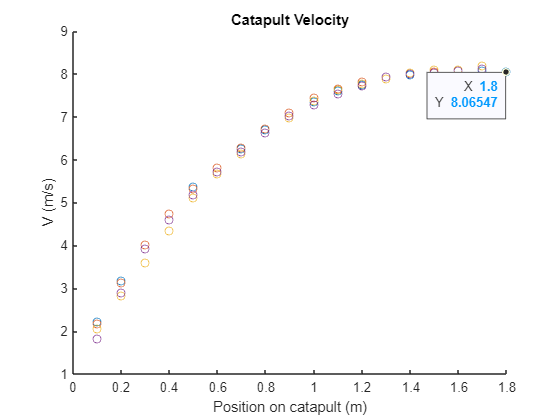

clf
hold on
catapult_new_time = 0:0.1:2;
for num = [1,2,3,4]
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.84, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_time);
    scatter(catapult_new_time, new)
end
hold off
ylabel("V (m/s)")
xlabel("Position on catapult (m)")
title("Catapult Velocity")

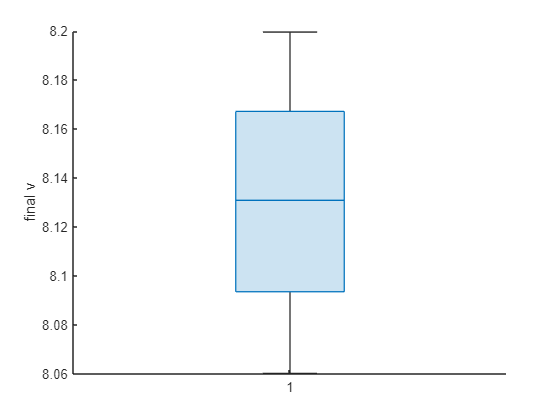

final_v = [];
clf
hold on
catapult_new_time = 0:0.1:2;
for num = 1:4
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.8, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_time);
    new = new(~isnan(new));
    new = new(new>1.75);
    final_v = [final_v new(end)];
end
boxchart(final_v);
hold off
ylabel("final v")

std(final_v)

ans = 0.0570